Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z

$$ans = 1.0137443442193619339806121273552$$

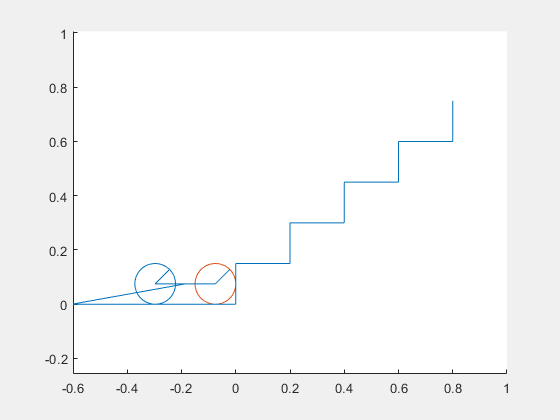

%Draw positions
drawfigure(sol1);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z

$$ans = 0.59427615842169444086761247965204$$

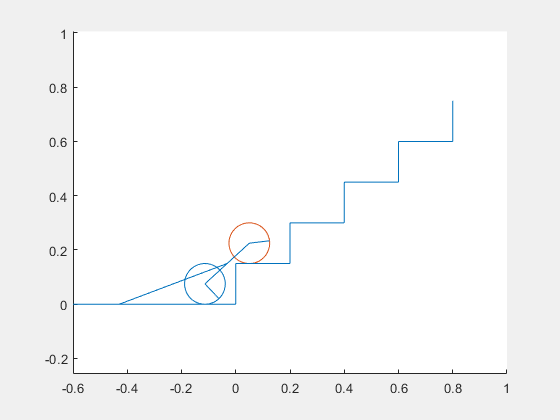

drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 0.97024699693327547752853529430384$$

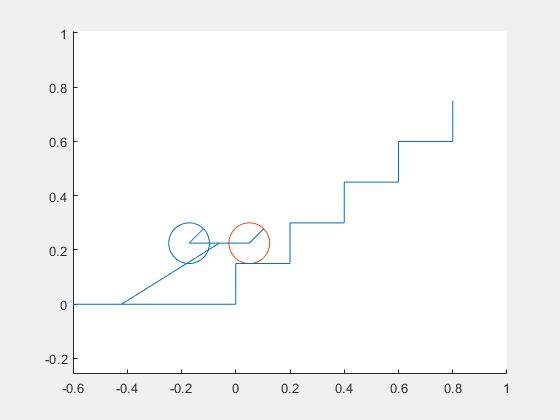

drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 0.97045043983878530066629142284365$$

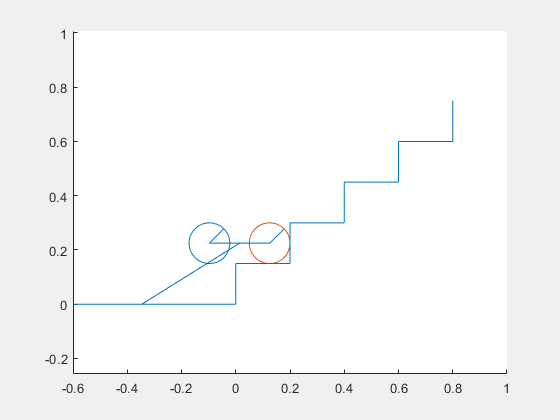

drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z

$$ans = 0.68070062519807303029846582572179$$

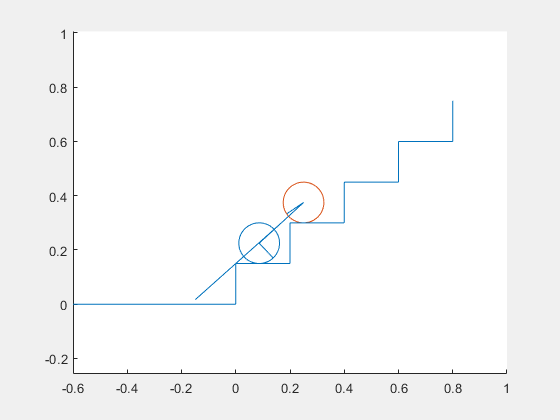

drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z

$$ans = 1.2279325028438281358655073652175$$

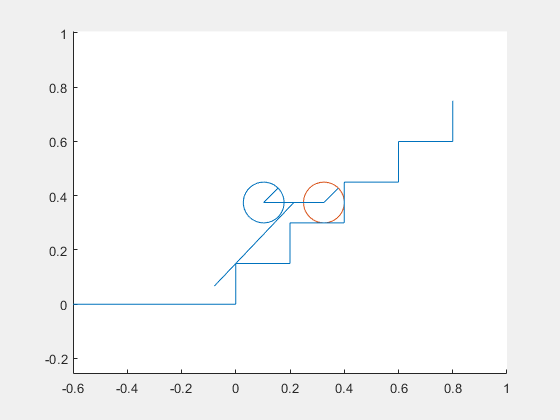

drawfigure(sol5);

%Stage 3:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z

$$ans = 1.1800240054091087229654098586133$$

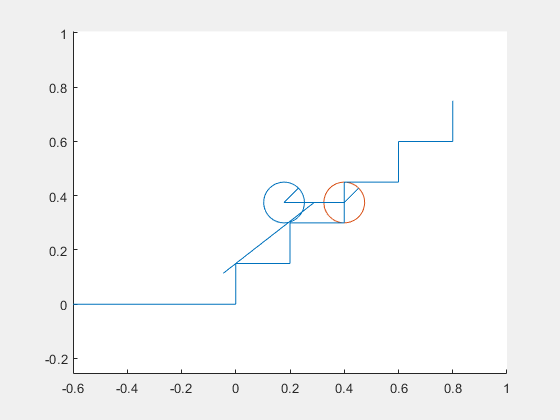

drawfigure(sol6);

%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
      C_friction7: 0.0
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: 0.0
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              a11: 0.0
              a12: 0.0
              a13: 0.0
              a21: 0.0
              a22: 0.0
              a23: 0.0
              a31: 0.0
              a32: 0.0
              a33: 0.0
              a41: 0.0
              a42: 0.0
              a43: 

solutions = []


solutions =

     []



for i = linspace(0, pi/2, 100)
    solutions = [solutions; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions(end).T_z
end

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

$$ans = 0.0$$

solutions(:).F_react72

$$ans = 10.817927615040289053005562180942$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

$$ans = 2.1138361422937974506974789790092$$

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

$$eqns\_motor = \left(\begin{array}{c} \mathrm{speed}={\mathrm{tv}}_{23}\\ T_{z}=\mathrm{voltage}-20\,\mathrm{speed}\\ \mathrm{stallTorque}=\frac{\mathrm{voltage}}{2} \end{array}\right)$$


%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)

sol2 = struct with fields:
      C_friction7: 0.0
        F_react51: 0
        F_react52: 74.34749034749034749034749034749
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react71: 0.0
        F_react72: -26.571650481731649908554133333626
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
        M_react53: -3.8097725947521865889212827988338
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              T_z: 12.0
              a11: 0.0
              a12: 0
              a13: 0.0

 
unsolved2 =
 
Empty sym: 0-by-1
 


%Start calculations
framesol = []


framesol =

     []



frameeqs = unsolved

Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

f = fieldnames(sol)

f = 172×1 cell array
    {'C_friction7'}
    {'F_react53'  }
    {'F_react61'  }
    {'F_react62'  }
    {'F_react63'  }
    {'F_react71'  }
    {'F_react73'  }
    {'I1'         }
    {'I2'         }
    {'I3'         }
    {'I4'         }
    {'I5'         }
    {'I6'         }
    {'I7'         }
    {'M_react61'  }
    {'M_react62'  }
    {'M_react63'  }
    {'N_idler'    }
    {'N_planet'   }
    {'N_sun'      }
    {'a13'        }
    {'a23'        }
    {'a33'        }
    {'a43'        }
    {'a51'        }
    {'a52'        }
    {'a53'        }
    {'a63'        }
    {'a73'        }
    {'f23'        }


nframes = length(framesol)

nframes = 40

for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end